This script is a part of the supplementary material for the following paper:

-  Jamshidi Idaji et al,  "Nonlinear Interaction Decomposition (NID): A Method for Separation of Cross-frequency Coupled Sources in Human Brain". doi: [https://doi.org/10.1101/680397](https://doi.org/10.1101/680397)

(C) Please cite the above paper (or a future peer reviewd version) in case of any significant usage of this script.

Corresponding Author: Vadim V. Nikulin (nikulin@cbs.mpg.de)

(C) Mina Jamshidi Idaji, Oct 2019, @ MPI CBS, Leipzig, Germany

jamshidi@cbs.mpg.de    .         minajamshidi91@gmail.com

https://github.com/minajamshidi/NID

# **Supplementary Code (2)**

# **Linear Mixture of Phase-Coupled Oscillations**

In this script, we will provide a simple simulation regarding the distribution of a linear mixture of two phase-coupled signals. For this purpose, we filter a white Gaussian noise in alpha (10Hz) and beta (20Hz) frequency bands and make phase-coupled signals out of them, and then investigate the distribution of their linear mixtures.

We want to filter a 10-min white Gaussian noise around 10Hz and 20Hz:

fs = 256;
order = 10*fs+1; % FIR filter order
n_samples = 10*60*fs;
phase_lag = pi/8;
times = (0:n_samples-1)/fs;
sig = randn(1, n_samples);

% build filter
Wn1 =  [9,11]/fs*2;
Wn2 =  [19,21]/fs*2;
b1 = fir1(order, Wn1);
b2 = fir1(order, Wn2);

% filter sig
u1 = filter(b1,1, sig);
x2 = filter(b2,1, sig);

We have extracted the phase and amplitude of the filtered signals. Now we make a faster oscillation phase-coupled to the slow oscillation and apply a time-shift to the faster oscillation:

x2_amp = abs(hilbert(x2));
u1_angle = angle(hilbert(u1));
u2 = real(x2_amp .* exp(1i*2*u1_angle + 1i*phase_lag));

cPLV = mean(exp(1i*2*angle(hilbert(u1)))...
    .*exp(-1i*angle(hilbert(u2))),2)

cPLV = 0.9228 - 0.3820i

Now, lets look at the distrubutions of u1 and u2:

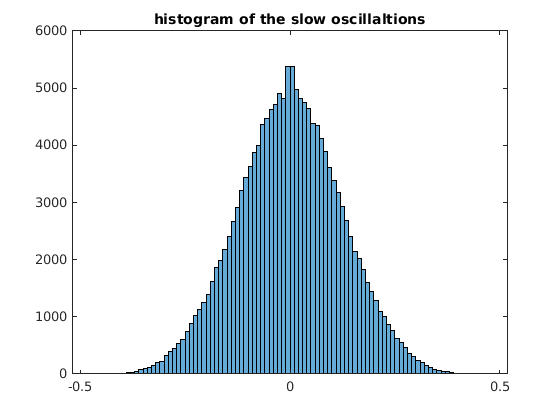

figure, histogram(u1),
title('histogram of the slow oscillaltions')

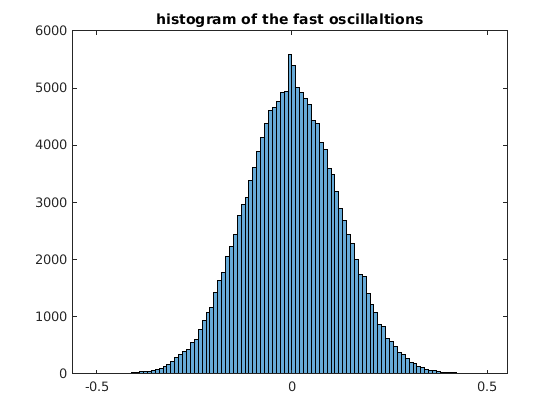


figure, histogram(u2),
title('histogram of the fast oscillaltions')


fprintf('kurtosis of u1 = %.2f\n', kurtosis(u1)-3)

kurtosis of u1 = -0.11


fprintf('kurtosis of u2 = %.2f\n', kurtosis(u2)-3)

kurtosis of u2 = 0.02


fprintf('skewness of u1 = %.2f\n', skewness(u1))

skewness of u1 = -0.00


fprintf('skewness of u2 = %.2f\n', skewness(u2))

skewness of u2 = 0.00


One can see they are quite Gaussian. Now we mix them linearly and check the distribution of the mixture:

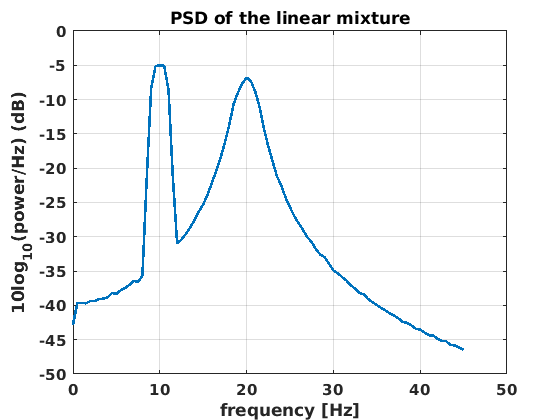

z = u1 + u2;
figure, plot_psd(z, fs, 45)
title('PSD of the linear mixture')

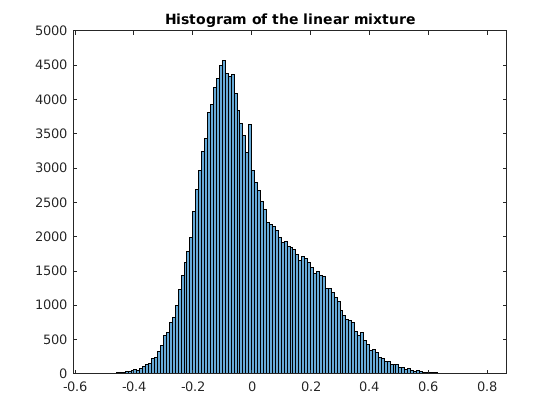

figure, histogram(z)
title('Histogram of the linear mixture')


fprintf('kurtosis of z = %.2f\n', kurtosis(z)-3)

kurtosis of z = -0.01


fprintf('skewness of z = %.2f\n', skewness(z))

skewness of z = 0.62


fprintf('5th moment of z = %.2f\n', mean((z/std(z)).^5))

5th moment of z = 4.38


fprintf('7th moment of z = %.2f\n', mean((z/std(z)).^7))

7th moment of z = 34.46


The distribution of the  linear mixture apparently deviates from Gaussian distribution. Please take a look at the odd higher order moments.

## Conclusion

In this script, we provided an exemplar simulation pipeline, where one can see that phase-coupled oscillations can be linearly mixed in the way that the distribution of the mixture is non-Gaussian. Note that here we did not use any non-Gaussinity maximization algorithm to find the optimum coefficients, and simply added the two narrow-band oscillations to each other.

## **Functions**

function plot_psd(x, fs, max_freq)
% a function to plot the PSD of the input signal
    [pxx,f] = pwelch(x, 2*fs, fs);
    f = f/pi * fs/2;
    pxx = pxx(f<=max_freq, :);
    f = f(f<=max_freq);
    plot(f, 10*log10(pxx), 'linewidth', 2);
    ylabel('10log_{10}(power/Hz) (dB)','fontsize', 12)
    xlabel('frequency [Hz]','fontsize', 12);
    set(gca, 'fontweight', 'bold', 'fontsize', 12)
    grid on,  
end

**Notification: **

THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.